# `Activity 5`

## `Pitch Scaling`

% Read in audio file
[y,fs] = audioread('sarigamapa.wav');
y = y(1:1000,1);

% pitch scaling factor 
% 0.5 for half speed 2 for double speed
pitch_factor = 0.5;

% Length of the audio signal
n = length(y);

% Find the pitch scaling factor in samples
pitch_factor_samples = round(pitch_factor * n);

% Initialize output signal
y_pitch_scaled = zeros(n,1);
for i = 1:n
    y_pitch_scaled(i) = interp1(1:n, y, i/pitch_factor);
end

sound(y_pitch_scaled,fs);

#### `Spectrum of Orginal Signal`

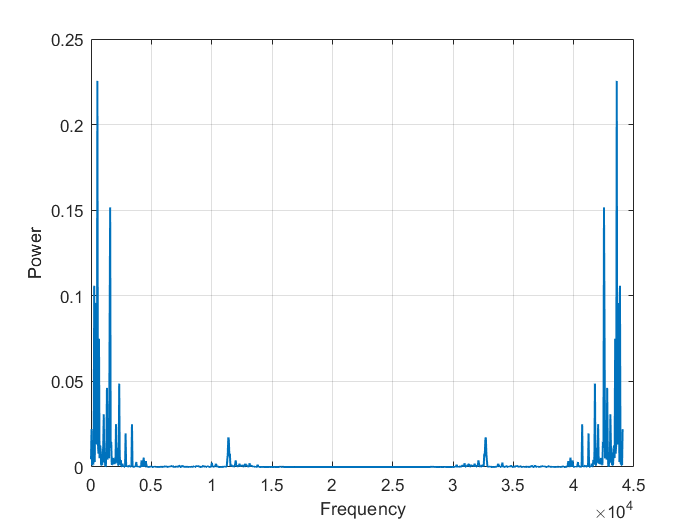

n = length(y);       
y_fft = fft(y);
f = (0:n-1)*(fs/n);     
power = abs(y_fft).^2/n;
plot(f,power,'LineWidth',1.2);
xlabel('Frequency');
ylabel('Power');
grid on

### `Spectrum of Pitch Scaled Signal`

n = length(y_pitch_scaled);        
y_scaled_fft = fft(y_pitch_scaled);
f = (0:n-1)*(fs/n)*pitch_factor;                 

y_scaled_fft =    2.1192 + 0.0000i
   4.1905 + 2.1273i
   0.9139 + 0.4358i
   1.1734 - 0.0520i
   0.4962 - 1.0988i
   1.7756 + 0.0066i
  10.2533 + 0.8545i
   1.3296 - 1.0854i
   5.4472 - 0.6235i
  -9.7925 - 0.0699i


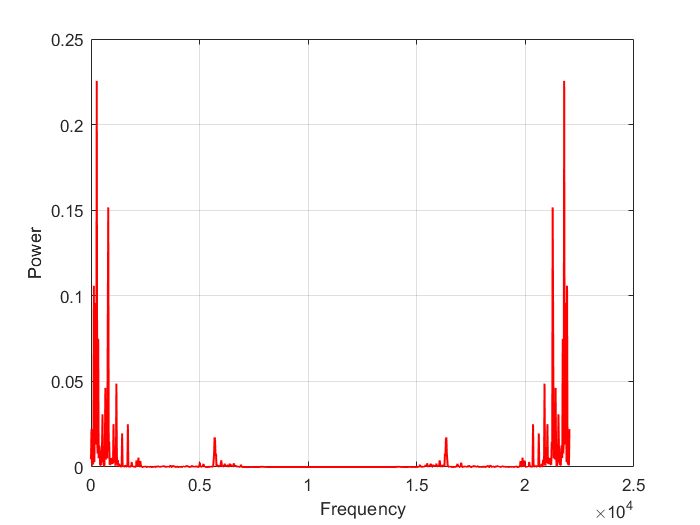

power = abs(y_scaled_fft).^2/n;
plot(f,power,'LineWidth',1.2,"Color",'r');
xlabel('Frequency');
ylabel('Power');
grid on